% Lab1 Task1
% 21.04.2019
% Xiao Tianqi
clear
clc
% Data
Y= [4.96 4.93 5.25 -5.26 -4.96 -4.99;4.96 4.94 5.56 -5.55 -4.89 -4.92;4.97 4.91 5.84 -5.81 -4.91 -4.92;4.86 4.83 6.09 -6.09 -4.86 -4.89;4.85 4.81 6.33 -6.34 -4.80 -4.82]'

Y =     4.9600    4.9600    4.9700    4.8600    4.8500
    4.9300    4.9400    4.9100    4.8300    4.8100
    5.2500    5.5600    5.8400    6.0900    6.3300
   -5.2600   -5.5500   -5.8100   -6.0900   -6.3400
   -4.9600   -4.8900   -4.9100   -4.8600   -4.8000
   -4.9900   -4.9200   -4.9200   -4.8900   -4.8200


A=[1 0 0;-1 1 0; 0 -1 1; 0 1 -1;1 -1 0;-1 0 0]

A =      1     0     0
    -1     1     0
     0    -1     1
     0     1    -1
     1    -1     0
    -1     0     0


P=0.02*0.02.*eye(6,6);
% initial value
x=[5;10;15];
%%sequencial
x_hat=inv(A'*P*A)*A'*P*Y(:,1);
e_1=Y(:,1)-A*x_hat;
s_02=e_1'*P*e_1/(6-3);
Sxx=s_02*inv(A'*P*A);
sigma(1,1)=Sxx(1,1);
sigma(2,1)=Sxx(2,2);
sigma(3,1)=Sxx(3,3);
dft(:,1)=x_hat-x;
H(:,1)=x_hat;
for i=2:5
   
   x_old=x_hat;
   s_old=s_02;
   Sxx_old=Sxx;
   yk=Y(:,i);
   x_hat=x_old+inv(s_old*inv(Sxx_old)+A'*P*A)*A'*P*(yk-A*x_old);
   dx=x_hat-x_old;
   s_02=(s_old*((i-1)*6-3+dx'*inv(Sxx_old)*dx)+(yk-A*x_hat)'*P*(yk-A*x_hat))/((i)*6-3);
   Sxx=s_02*inv(s_old*inv(Sxx_old)+A'*P*A);
   sigma(1,i)=Sxx(1,1);
   sigma(2,i)=Sxx(2,2);
   sigma(3,i)=Sxx(3,3);
   H(:,i)=x_hat;
   dft(:,i)=x_hat-x;

end
x_hat

x_hat =     4.9140
    9.7980
   15.6100


drift=x_hat-x

drift =    -0.0860
   -0.2020
    0.6100


formal_error=sqrt(sigma)

formal_error =     0.0126    0.0514    0.0608    0.0689    0.0749
    0.0178    0.0727    0.0860    0.0974    0.1059
    0.0218    0.0891    0.1053    0.1193    0.1297


%% separate
% sum=zeros(3,1);
for i=1:5
    H_hat=A\Y(:,i);
    Hs(:,i)=H_hat;
    e=Y(:,i)-A*H_hat;
    Sxx_s=e'*P*e/(6-3)*inv(A'*P*A);
    sigma_s(1,i)=Sxx_s(1,1);
    sigma_s(2,i)=Sxx_s(2,2);
    sigma_s(3,i)=Sxx_s(3,3);
%     sum=sum+sigma_s(:,i);
%     s(:,i)=sum;
end
Hs

Hs =     4.9750    4.9400    4.9450    4.8750    4.8350
    9.9200    9.8550    9.8550    9.7200    9.6400
   15.1750   15.4100   15.6800   15.8100   15.9750


H_ave=(sum(Hs')/5)'

H_ave =     4.9140
    9.7980
   15.6100



formal_error_s=sqrt(sigma_s)

formal_error_s =     0.0126    0.0187    0.0168    0.0122    0.0096
    0.0178    0.0265    0.0238    0.0173    0.0135
    0.0218    0.0324    0.0292    0.0212    0.0166


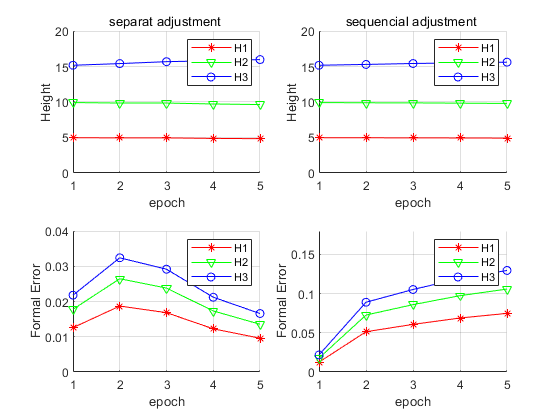


%%display
p=1:5;
subplot(2,2,1)
hold on
grid on
axis ([1 5 0 20])
plot(p,Hs(1,:),'*-r')
plot(p,Hs(2,:),'v-g')
plot(p,Hs(3,:),'o-b')
xlabel('epoch')
ylabel('Height')
legend('H1','H2','H3')
title('separat adjustment ')


subplot(2,2,2)
hold on
grid on
axis ([1 5 0 20])
plot(p,H(1,:),'*-r')
plot(p,H(2,:),'v-g')
plot(p,H(3,:),'o-b')
xlabel('epoch')
ylabel('Height')
legend('H1','H2','H3')
title('sequencial adjustment ')

subplot(2,2,3)
hold on
grid on
axis ([1 5 0 0.04])
plot(p,formal_error_s(1,:),'*-r')
plot(p,formal_error_s(2,:),'v-g')
plot(p,formal_error_s(3,:),'o-b')
xlabel('epoch')
ylabel('Formal Error')
legend('H1','H2','H3')

subplot(2,2,4)
hold on
grid on
axis ([1 5 0 0.18])
plot(p,formal_error(1,:),'*-r')
plot(p,formal_error(2,:),'v-g')
plot(p,formal_error(3,:),'o-b')
xlabel('epoch')
ylabel('Formal Error')
legend('H1','H2','H3')

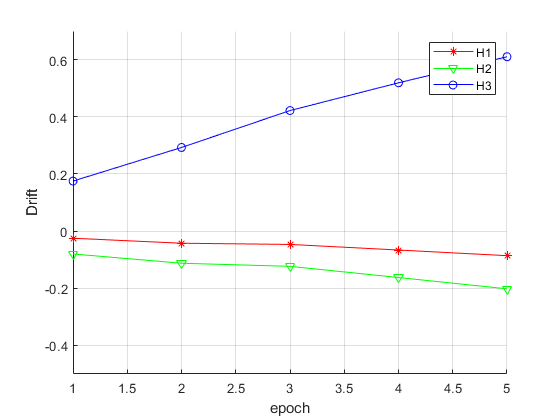


figure(2)
hold on
grid on
axis ([1 5 -0.5 0.7])
plot(p,dft(1,:),'*-r')
plot(p,dft(2,:),'v-g')
plot(p,dft(3,:),'o-b')
xlabel('epoch')
ylabel('Drift')
legend('H1','H2','H3')